# Multi-Microphone-Method

## 1. Before we start

Before proceeding we will `clear` the workspace, and run the `dir` command to ensure that we are in the correct workspace. You should be able to see a folder named `tutorial_functions`. 

clear
dir
addpath(genpath('tutorial_functions'))

.                   .gitignore          LC1_c.gif           P8kW                WK00_Spectral.mlx   WK03_FTM.mlx        
..                  DTL                 MMM.gif             TDL                 WK01_MMM.mlx        tutorial_functions  
.git                LC1.gif             P12kW               TESTER.m            WK02_FTF.mlx        



## 2. Introduction

In this tutorial we will learn to use the multi-microphone-method (MMM) to:

- Reconstruct the pressure field in the geometry.

- Compute the acoustic velocity fluctuations.

First let's take a look at the configuration of the combustor.

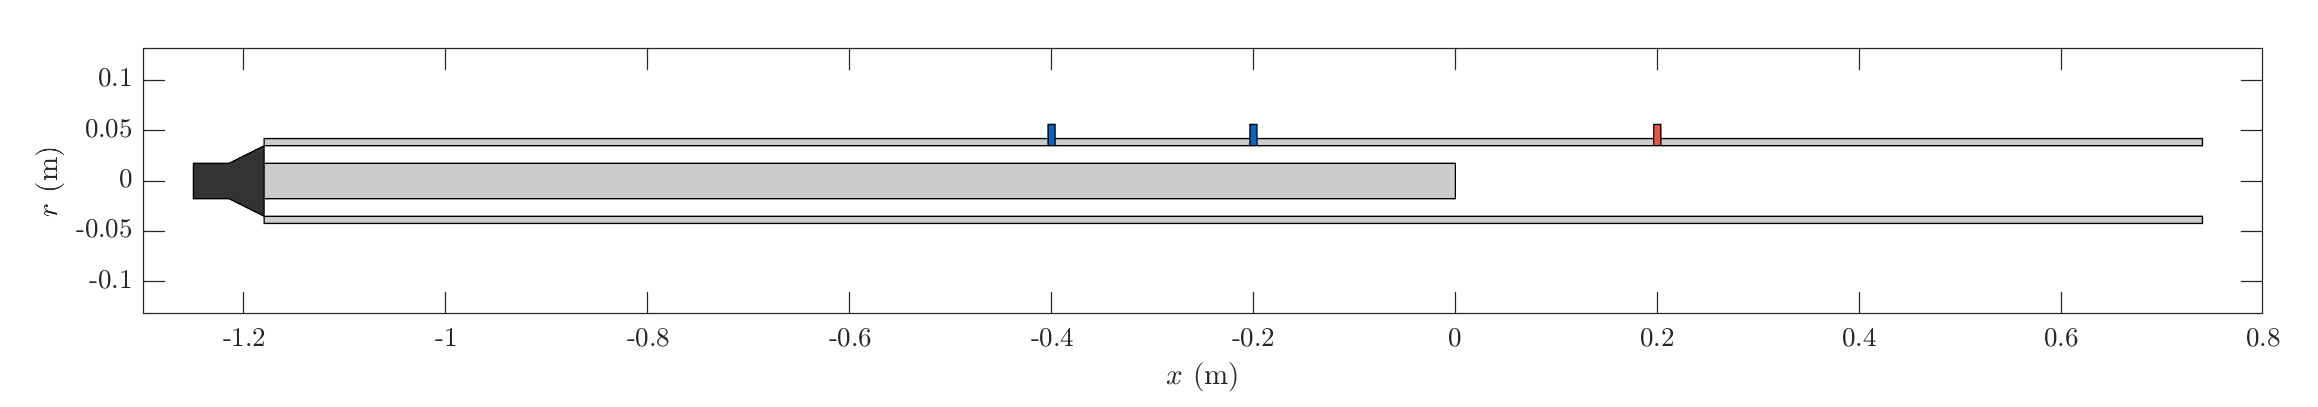

Fig. 1 Schematic of the combustor.

We can think of it as a duct with a rod in the middle. The rod will act as the flame holder in later parts of the tutorial. The configuration is currently equipped with 2 differential pressure transducers (blue probes), 1 hot wire anemometer (red probe) and a speaker located at the inlet.  We will use the speaker to force the flow to take the adequate measurements. Finally, notice that the dump plane (end of the rod) is located at $x = 0$.

Before proceeding we first need to make some assumptions: 

- The flow in the duct is governed by the Euler equations, i.e., viscous effects are neglected. 

- The flow is 1D, i.e., there is no variation in the $r$ or $\theta$ directions. 

- The flow can be decomposed into a mean and a fluctuating part, i.e., $p(x,t) = \bar p(x) + p'(x,t)$ 

Under the previous assumptions, in the regions where the mean flow is constant $x\in \left(-1\ldotp 18,0\right)\cup \left(0,0\ldotp 74\right)$ m,  the Euler equations can be linearized and after some manipulation one can obtain a convected wave equation:


$$\frac{1}{{\bar{c} }^2 }\frac{D^2 p^{\prime } }{D^2 \;t}+\nabla^2 p^{\prime } =0,\;\;\;\;\;\;\;\;\;\textrm{Eq}\ldotp \left(1\right)\;$$


This has two possible solutions (Riemann invariants)  given by the functions:


$$f\left(t-\frac{x}{\bar{c} +\bar{u} \;}\right),\;\;\;\;\;\;g\left(t+\frac{x}{\bar{c} -\bar{u} \;}\right)$$


Here$f$ and $g$ can be any function. These functions are also called plane wave solutions since they only propagate in the $x$ direction.  When only plane waves propagate, the pressure and the velocity fields take the form:


$$\begin{array}{l}
p\left(x,t\right)=\bar{p} \left(x\right)+f\left(t-\frac{x}{\bar{c} +\bar{u} \;}\right)+g\left(t+\frac{x}{\bar{c} -\bar{u} \;}\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Eq}\ldotp \left(2a\right)\\
u\left(x,t\right)=\bar{u} \left(x\right)+\frac{1}{\bar{\rho \;} \bar{c} }\left(f\left(t-\frac{x}{\bar{c} +\bar{u} \;}\right)-g\left(t+\frac{x}{\bar{c} -\bar{u} \;}\right)\right)\;\;\;\;\;\;\;\;\textrm{Eq}\ldotp \left(2b\right)
\end{array}$$


From this equations it is clear that if we know the values of $f$ and $g$, which we can obtain from pressure measurements, we can reconstruct the flow field and then use that pressure field to obtain acoustic velocity measurements. 

## 3. Objectives

For the configuration given in Fig. 1 the task will be:

- Obtain the velocity fluctuations at  $x = 0.2$m 

- Compare them with those obtained via hot wire anemometry.    

## 4. Setting up the simulation

For the configuration shown in Fig. 1 we will assume that inlet of the configuration is choked (in experiments this type of boundary condition is useful to decouple the acoustics upstream of the combustor, i.e., fuel/oxidizer lines), and we will specify the velocity of the flow $\bar u_1$ and its temperature $\bar T_1$.  We will also assume that the outlet of the configuration is open to the atmosphere and specify the outlet pressure $\bar p_2$. At this stage we will not consider any heat source and set the mean heat release to be zero $\bar Q = 0$. Notice that we are using the subscripts 1 and 2 to denote the mean flow conditions before and after the area expansion at $x = 0$ respectively as shown in Fig. 2:

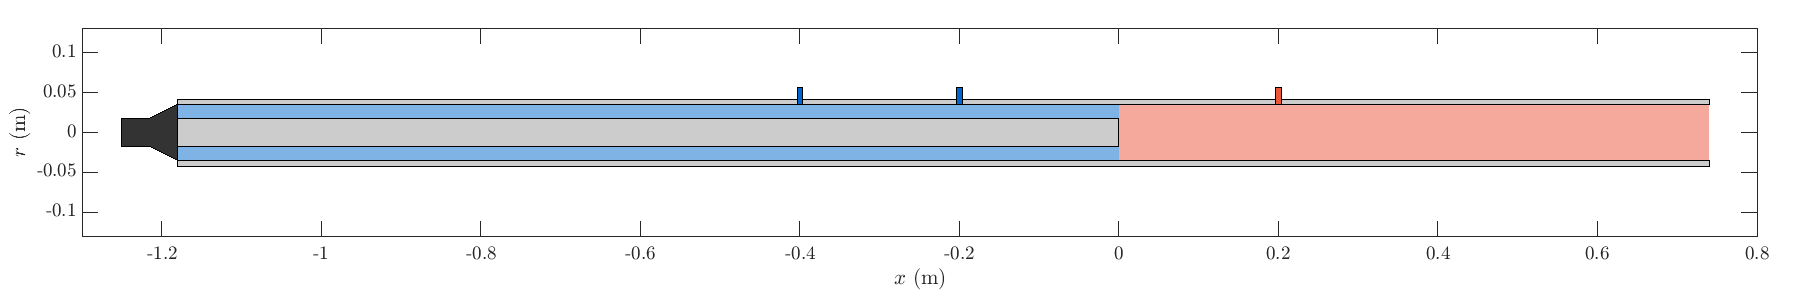

Fig. 2: Mean flow regions. In blue we show regions 1 (before the area expansion),

 and in red we show region 2 (after the area expansion).

% Define inlet and outlet conditions:
u1 = 20;       % Inlet velocity (m/s)
T1 = 293;      % Inlet temperature (m/s)
p2 = 101300;   % Outlet pressure (Pa)
Qbar = 0;      % Heat release rate (W)

In the absence of heat release, the flow is naturally unforced. Therefore in order to measure the acoustic response of the configuration we need to force the configuration:

% Define Forcing Conditions:
Forcing.Speaker = 'ON';
Forcing.Voltage = 1;     % (V)
Forcing.Frequency = 200; % (Hz)
Forcing.Speaker_Downstream = 'OFF';

In the last step we need to set up the measurement probes as well as the sampling frequency and length of the measurements. For the time being we will keep the PMT off, since there is no heat release at this moment. 

% Sampling frequency: 
Measurement.Fs = 5000; % (Hz)
% Length of the measurements:
Measurement.Time = 2; % (s)

% Photomultiplier:
Measurement.PMT = 'OFF';
% Differential Microphones:
x_mic =  [-0.2,-0.4]; % (m)
Measurement.Mic = 'ON';
Measurement.Mic_Pos  = x_mic;
% Hot wire anemometry:
x_hw = 0.2; % (m) 
Measurement.HWA = 'ON';
Measurement.HWA_Pos = x_hw;

Before proceeding with the simulation, let's preview the set up.

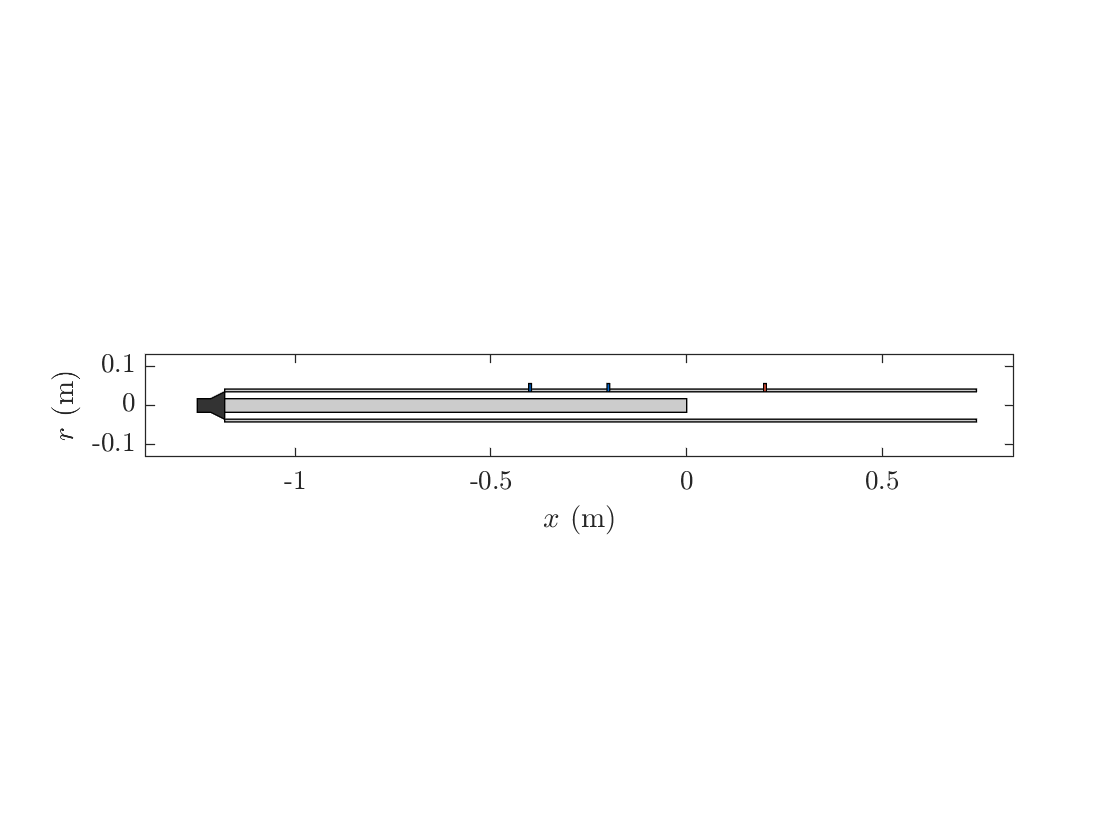

% Preview set up:
figure

fn_plot_config(Forcing,Measurement)

## 5. Running the simulation

Now lets, run the simulation, make sure you wait until it says "Finished". 

[Mean,Geom,Signals,Sim] = Run_Simulation(u1,T1,p2,Qbar,Forcing,Measurement);

Progress: 0%, 5%,  10%,  15%,  20%,  25%,  30%,  35%,  40%,  45%,  50%,  55%,  60%,  65%,  70%,  75%,  80%,  85%,  90%,  95%, 
 Finished 


In the meantime take a look at the following animation of the simulation:

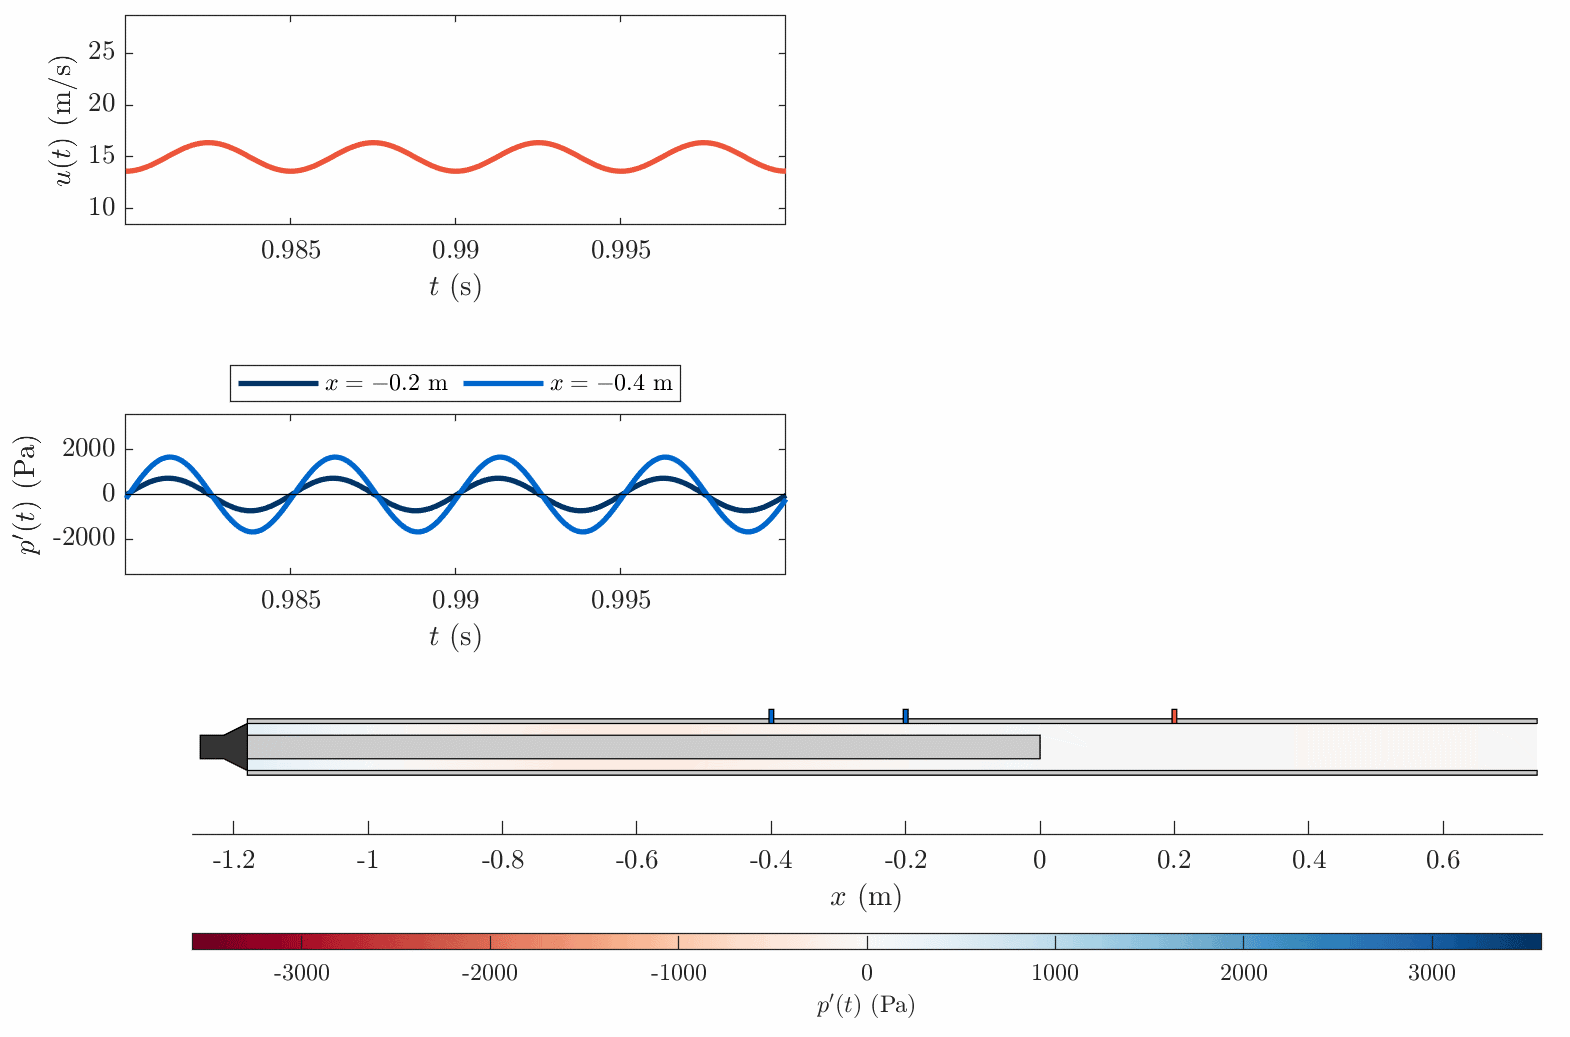

Fig. 3 Simulation of the forced acoustic field. 

A few things to think about:

- Can you identify the boundary conditions from this visualization? 

- Where are the microphones with respect to the pressure nodes/antinodes?

You may notice that none of the microphones are located at the pressure antinodes, these locations may be favourable because they are the most "observable" regions. However, in a real experiment we cannot visualize this field, that is why we use the multi-microphone-method, to reconstruct this field. 

**Optional**:

If you want to visualize the acoustic field in the forced combustor, uncomment and run the following commands. You may want to change the starting and end points, but try to keep the time difference around $\Delta t = 0.02$ s, or else terminate the animation using the `ctrl+c` command. 

% t_start = 1;
% t_end = t_start + 0.02;
% Num_of_time_steps_in_plot = 200; 
% stepsize = 2;
% fn_view_simulation(Sim,stepsize,t_start,t_end,Num_of_time_steps_in_plot)

## 6. Analysing pressure and velocity data

Lets begin by plotting the pressure and velocity measurements. Keep in mind that the pressure measurements obtained from the microphones will only provide us with the fluctuating part $p'(x,t)$ (since they are "differential pressure" transducers), while the velocity measurement given by the hot wire anemometer will provide the total velcocity $\bar u (x) + u'(x,t)$.

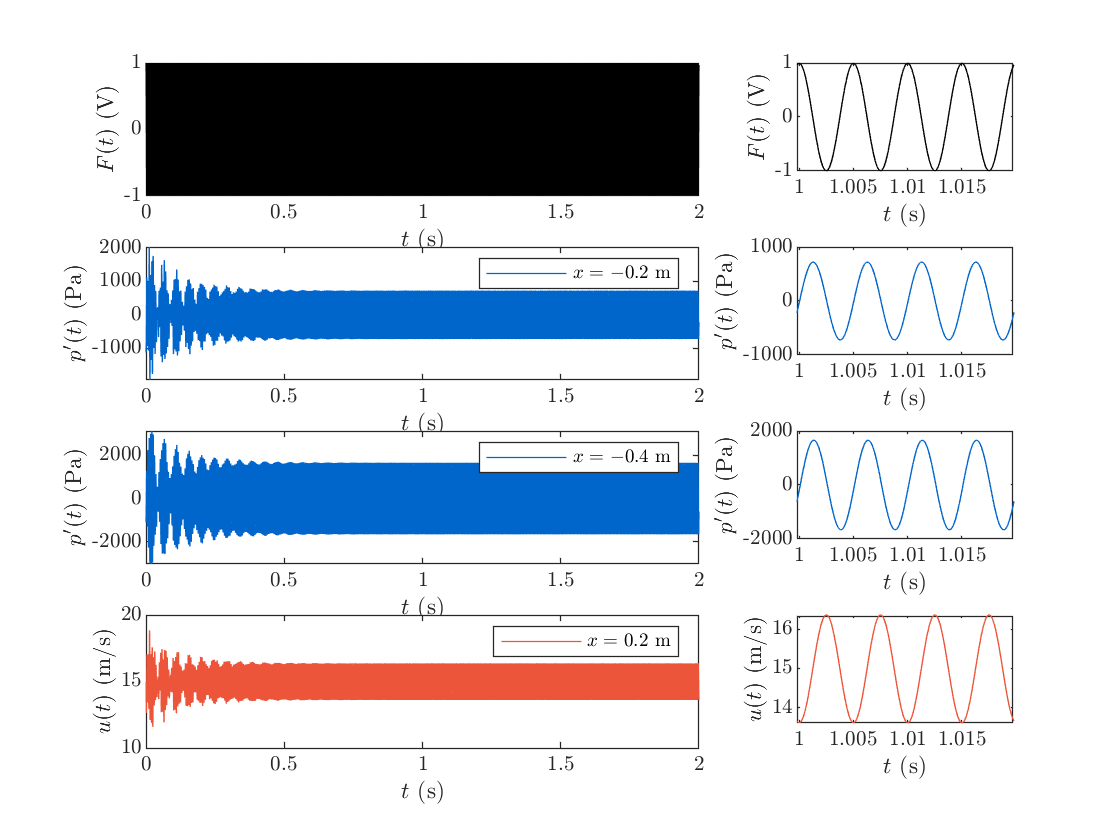

zoom_in_time_steps = 100; 
fn_plot_Signals(Signals,Measurement,zoom_in_time_steps)

We can see that after an initial transient that lasts until about $t = 0.5$s the signals reach a steady amplitude.  

### a) Spectral analysis

Before extracting all the relevant information to reconstruct the acoustic field, let's first analyse the spectra of the signals. For this we will use the function we created earlier `fn_spectral_est.` This analysis is useful to study the frequency content of a signal and determine the strength of the harmonics.  

Since we have a forcing signal we will use it as the reference and cross correlate all the signals with it. First lets examine the frequency content of the first microphone:

t     = Signals.t;
xref  = Signals.Forcing;
pp_x1 = Signals.P_mic(1,:);
% Spectral estimation
[f,ph_x1] = fn_spectral_est(t,pp_x1,xref,'welch');
% Plot
figure
semilogy(f,abs(ph_x1))
xlim([f(1) f(end)])
xlabel('$f$ (Hz)','Interpreter','Latex')
ylabel('$|\hat{p}|$ (Pa)','Interpreter','Latex')

As expected there is a peak at 200 Hz, there are also many other peaks but their amplitude is substantially smaller (look at their magnitude). Some of those peaks appear due to the transient at the start, so cropping the signal may improve the spectral estimate. 

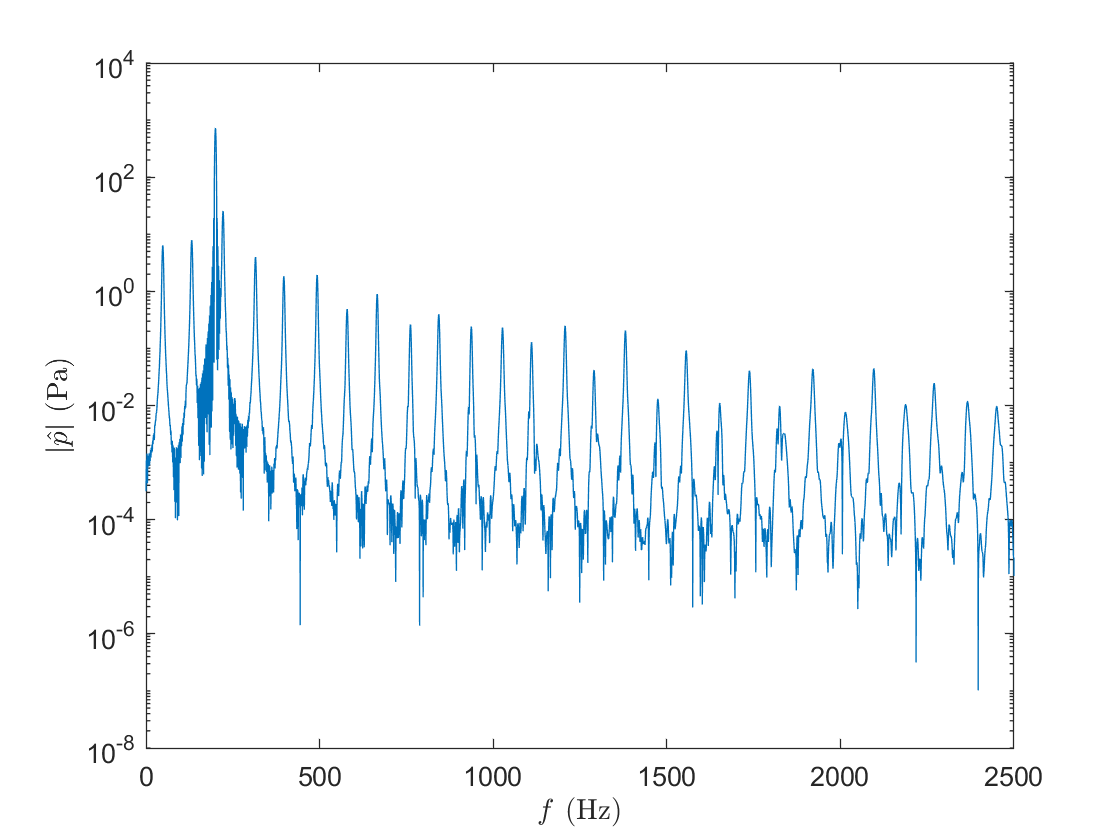

% Cropping the signal

indx1  = find(t == 0.5);
tc     = t(indx1:end);
xrefc  = xref(indx1:end);
pp_x1c = pp_x1(indx1:end);
% Espectral estimation
[f,ph_x1] = fn_spectral_est(tc,pp_x1c,xrefc,'welch');
% Plot
figure
semilogy(f,abs(ph_x1))
xlim([f(1) f(end)])
xlabel('$f$ (Hz)','Interpreter','Latex')
ylabel('$|\hat{p}|$ (Pa)','Interpreter','Latex')

As we can see some of the other (harmonic) peaks become smaller. We can easily find the location of the peak using:

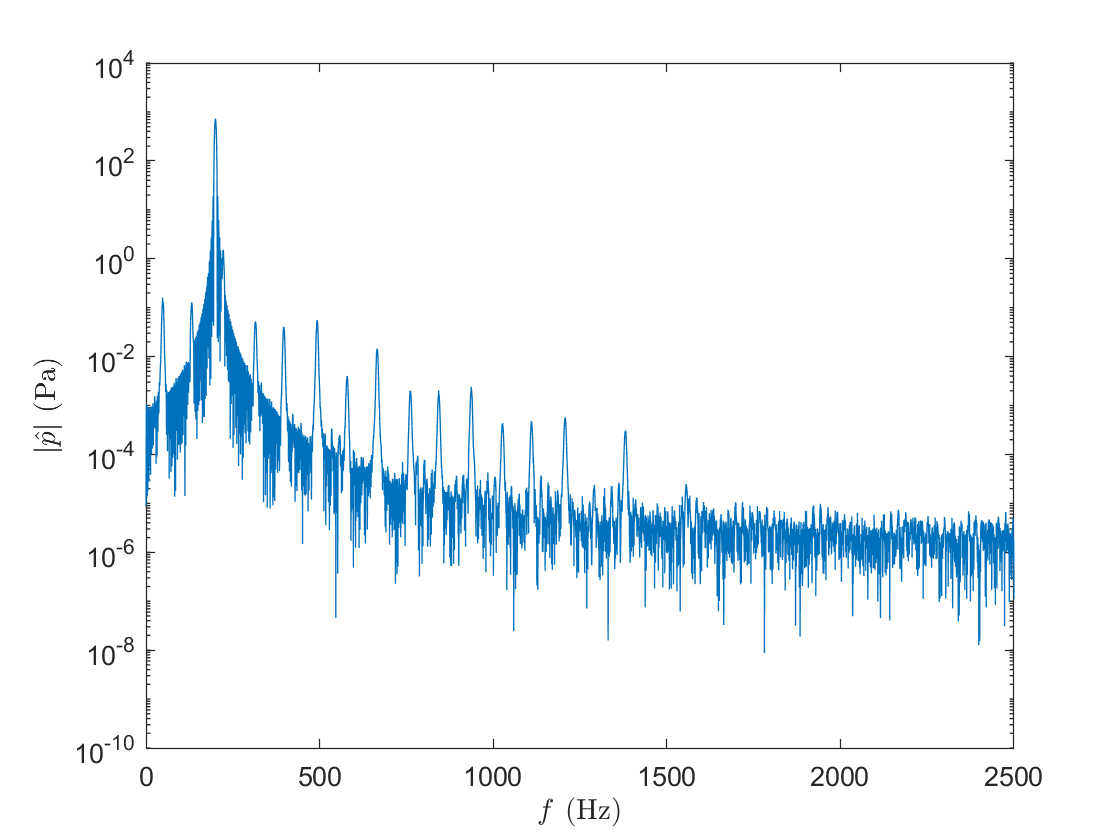

[ph_max,indx_max] = max(ph_x1);

ph_max_abs = abs(ph_max)
freq = f(indx_max)

ph_max_abs = 724.4825

freq = 200.0046

The peak at a frequency of 200 Hz has an amplitude of approximately $|\hat{p}|$= 725 Pa, which coincides with the previous plots.  We will use this information to reconstruct the acoustic field.

### b) Reconstruction of the acoustic field

The aim of this section is to estimate the amplitudes of the acoustic waves and to propagate them in the configuration:

#### i) Estimation of wave amplitudes in a duct

By considering only harmonic fluctuations of the form $p'(x,t) = \mathcal{R} \left[ \hat{p}(x) \exp(i\omega t)\right]$ and similar for $u'(x,t)$,  the fluctuating parts of Eq. (2) can be rewritten as:


$$\hat{p} \left(x\right)=F\;\exp \left({i\;k}_+ \;x\right)+G\;\exp \left({i\;k}_- \;x\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Eq}\ldotp \left(3a\right)$$
        


$$\hat{u} \left(x\right)=\frac{1}{\bar{\rho \;} \bar{c} }\;\left(F\;\exp \left({i\;k}_+ \;x\right)-G\;\exp \left({i\;k}_- \;x\right)\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Eq}\ldotp \left(3b\right)$$


where


$$k_+ =-\frac{\omega \;}{\bar{c} +\bar{u} },{\;\;\;\;\;\;\;\;\;k}_- =\frac{\omega }{\bar{c} -\bar{u} }$$


Hence if we can compute the (complex) coefficients $F$ and $G$ we should be able to reconstruct the pressure field in the entire duct.  In the previous section we estimated the value of $\hat{p}(x_1)$ and $\omega$ using spectral estimates. Then, by knowing $\hat{p}(x_1)$, $\hat{p}(x_2)$,..., $\hat{p}(x_n)$  and $\omega$ we can compute the values of the wave amplitudes $F$ and $G$ as follows:


$$\left\lbrack \begin{array}{c}
\hat{p} \left(x_1 \right)\\
\hat{p} \left(x_2 \right)\\
\vdots \\
\hat{p} \left(x_n \right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\exp \left({i\;k}_+ \;x_1 \right) & \exp \left({i\;k}_- \;x_1 \right)\\
\exp \left({i\;k}_+ \;x_2 \right) & \exp \left({i\;k}_- \;x_2 \right)\\
\vdots  & \vdots \\
\exp \left({i\;k}_+ \;x_n \right) & \exp \left({i\;k}_- \;x_n \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
F\\
G
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Eq}\ldotp \left(4\right)$$


or


$$b=A\;x$$


Which can be solved using least squares, in MATLAB we solve it using:` x = A\b. `

`NOTE:`**  This method will only work if the base flow properties of the duct are constant. **

This is **not** our case, since we want the velocity measurement **after an area expansion** located at $x = 0$. So first, let's reconstruct the acoustic field in the region $x < 0$ and in the next section we will deal with the change in area.

**Tasks**:

A) Finish the function `fn_MMM:`

- Using the function `fn_spectral_est `compute the values of $\hat{p}(x_1)$, $\hat{p}(x_2)$and $\omega$. 

- Using Eqs.(3) and (4) obtain the values of $F$ and $G$ in the duct. 

B) Finish the function `fn_acoustic_field:`

- Using Eq. (3) compute $\hat{u}(x)$ and $\hat{p}(x)$.

C) Run the following code to reconstruct the acoustic field in the region $x<0$. If done correctly, you should obtain the following values: $F = -836.9+330.1i$ Pa, $G = 896.6 + 260.0i$ Pa and $\omega = 2\pi f = 1256.7$ rad/s. 

% Multi-Microphone-Method:
[F,G,omega] = fn_MMM(Mean,Signals,Measurement)
% Signal Reconstruction:
x = linspace(-1.18,0,1000);

F = -8.3690e+02 + 3.3011e+02i

G = 8.9658e+02 + 2.5999e+02i

omega = 1.2567e+03

[ph,uh] = fn_acoustic_field(Mean,F,G,omega,x);

Having the acoustic field reconstructed, we can visualize it. Here we plot the modeshapes in the region $x \in [-1.18,0]$ m.

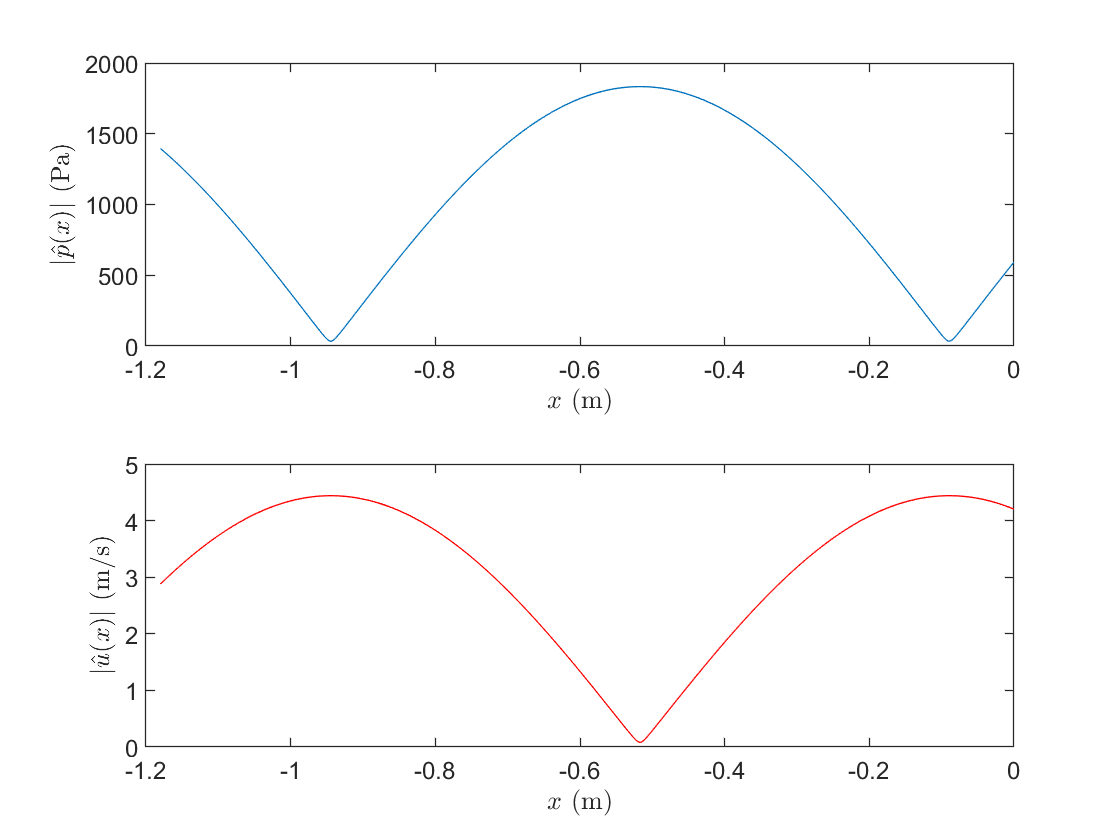

% Plot modulus of acoustic field
figure
tiledlayout(2,1)
nexttile
plot(x,abs(ph))
xlabel('$x$ (m)','Interpreter','Latex')
ylabel('$|\hat{p}(x)|$ (Pa)','Interpreter','Latex')
nexttile
plot(x,abs(uh),'r')
xlabel('$x$ (m)','Interpreter','Latex')
ylabel('$|\hat{u}(x)|$ (m/s)','Interpreter','Latex')

- How does the pressure mode shape compare with the one we visualized in the animation above?

#### ii) Wave propagation in (compact) area changes

The aim is to reconstruct the velocity at $x = 0.2$ m, and as we can see from Fig. 1 there is an area change at $x = 0$. 

In the absence of a mean flow ($\bar{u} = 0$), or at very low Mach numbers (as in our case) we have that at the interface $x = 0$.


$$\begin{array}{l}
\;\;\;\;\;\hat{p_2 } =\hat{p_1 } \\
A_2 \hat{u_2 } =A_1 \hat{u_1 } 
\end{array}$$


where the subscript 2 denotes the conditions after the area jump and the subscript 1 denote the conditions before the area jump. This can be rewritten as a transfer matrix:


$$\left\lbrack \begin{array}{c}
\hat{p_2 } \\
\hat{u_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & \frac{A_1 }{A_2 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\hat{p_1 } \\
\hat{u_1 } 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Eq}\ldotp \left(5\right)$$


Knowing $\hat{p}_2$ and $\hat{u}_2$ and the mean properties after the area change we can compute the new values of $F$ and $G$ and propagate the signal until we reach the position $x = 0.2$m (or the end of the configuration). 

**Tasks**

- Using the function fn_acoustic_field compute the values of $\hat{u}_1 = \hat{u}(0)$ and $\hat{p}_1 = \hat{p}(0)$.

- Finish the function `fn_Area_Change. U`sing Eq. (5) compute the values of  $\hat{p}_2$ and $\hat{u}_2$. Then Using Eq.(3) compute the values of $F$ and $G$ in the next duct.

- Using the new values of $F$ and $G$ propagate the signal until $x = 0.2$ m.

- Compare your with that obtained via HWA.

% 1) Compute the values of uh1 and ph1 at x = 0
x0 = 0;
[ph1,uh1] = fn_acoustic_field(Mean,F,G,omega,x0);
% 2) Compute F and G after the area expansion:
[F2,G2] = fn_Area_Change(Mean,Geom,ph1,uh1,omega,x0);
% 3) Propagate the signal to x = 0.2 m:
[~,uh] = fn_acoustic_field(Mean,F2,G2,omega,x_hw);

To compare the value with the hotwire anemometer, we need to add the mean value to our velocity signal and make it harmonic in time, since:


$$u\left(x,t\right)=\bar{u} +u^{\prime } \left(x,t\right)=\bar{u} +\Re \left\lbrack \hat{u} \left(x\right)\exp \left(i\;\omega \;t\right)\right\rbrack \;$$


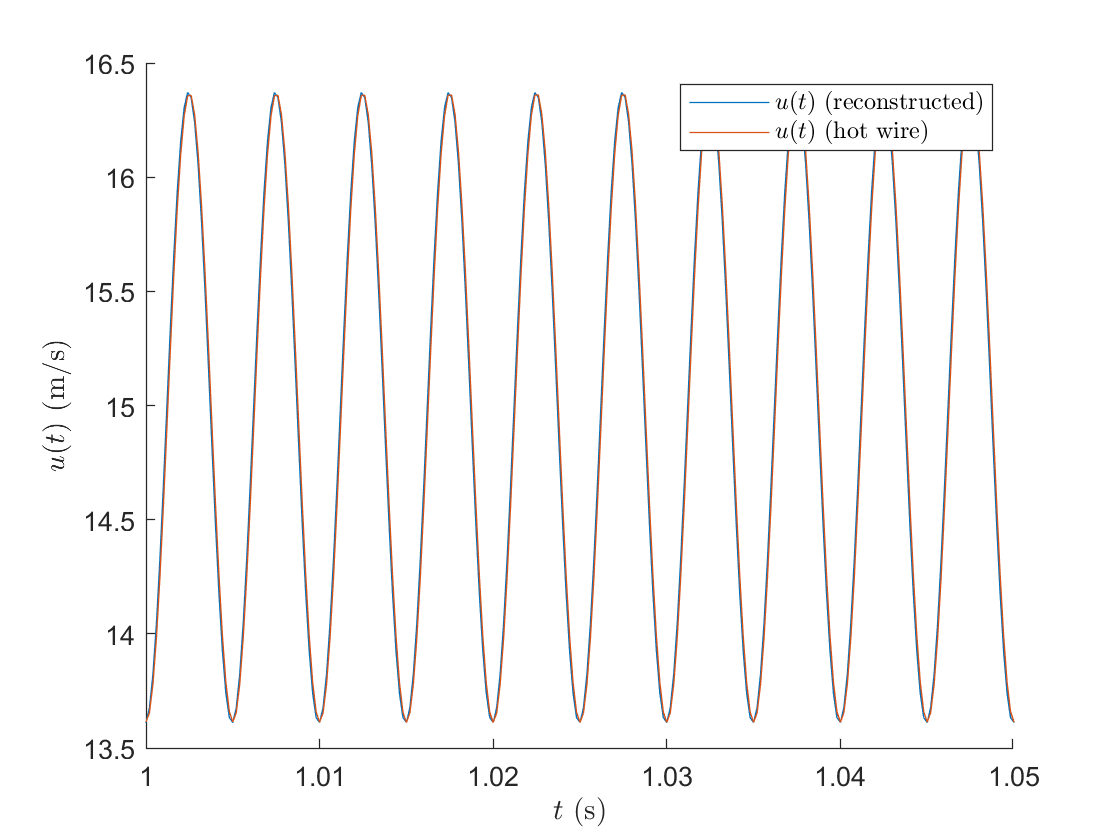

% Retrieve the mean velocity
ubar = Mean.u2;
% Time domain (harmonic) signal
u = ubar + real(uh*exp(1i*omega*tc));
% Hot wire signal (cropped)
u_hwa = Signals.U_hw(indx1:end);

% 4) Plot and compare signals
figure('Color','w')
hold on
plot(tc,u)
plot(tc,u_hwa)
xlabel('$t$ (s)','Interpreter','Latex')
ylabel('$u(t)$ (m/s)','Interpreter','Latex')
legend('$u(t)$ (reconstructed)','$u(t)$ (hot wire)','Interpreter','Latex')
xlim([1 1.05])

## 7. Further considerations

In this tutorial we only used 2 microphones, so we did not perform least squares, we just solved the full system of equations Eq. (4). Ideally you want to use at least 3 of them (although this is not always possible in an experiment) with a variable distance in between them, such that you have to do a least squares approximation. This is particularly useful when at a specific frequency a pressure node occurs at the location of one of the microphones. 

**Optional Tasks**

**Repeat the previous exercise but:**

- Change the forcing frequency or the micrphone locations and try to set a pressure node at one of the microphone positions. Can you still reconstruct the signal?

- Change the location of the hot wire and try to reconstruct the signal at the new location. 

- Increase the number of microphones (by adding more locations) and try to reconstruct the signal. You can do this by changing the following line at the begining of the turotial e.g.:

Measurement.Mic_Pos  = [-0.2,-0.4,-0.7];

Furthermore, in this tutorial we completely neglected the influence of convective disturbances, In some cases there are vorticity waves travelling at the mean flow velocity. These act as a new term in the velocity field, but not in the pressure field. Similarly we have neglected the presence of entropy waves which appear as an extra term in the density/temperature field. Therefore if such waves are present care needs to be taken. 